# Ejercicios raíces

5.7 Determine the roots of f (x) = −12 − 21*x + 18*x^2 − 2.75*x^3 graphically. In addition, determine the first root of the function with bisection (linear interpolation and Newton-Raphson)

f=@(x)-12-21*x+18*x^2-2.75*x^3;
xl=-1;
xu=1;
[xr1,i1]=BiseccionMetodo(f,xl,xu)

xr1 = -0.4147

i1 = 55

[xr2,i2]=interLin(f,xl,xu)

xr2 = -0.4147

i2 = 30

[xr3,i3]=nr(f, xu)

xr3 = -0.4147

i3 = 12

fplot(f,[-5 6])

grid on;

This plot indicates that roots are located at about –0.4, 2.25 and 4.7. La primera raíz está en [-1,0].

z=[-2.75 18 -21 -12];
roots(z)

ans =     4.7403
    2.2198
   -0.4147


5.8 Locate the first nontrivial root of sin(x) = x^2 where x is in radians. Use a graphical technique and a numerical algorithm..

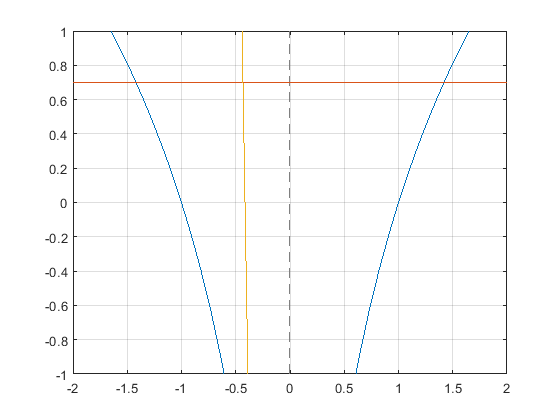

g1=@(x) sin(x);
g2=@(x) x^2;
hold off;

fplot(g1,[-5 5])
hold on;
fplot(g2,[-5 5])

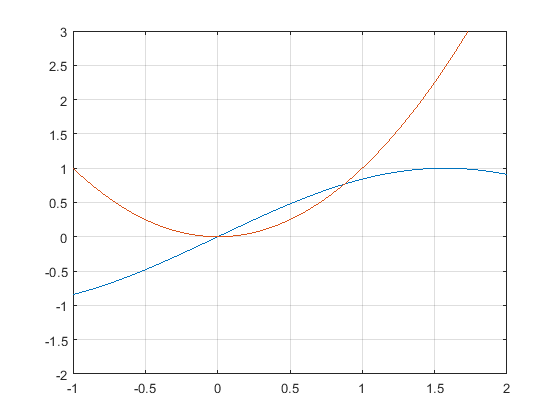

hold off;
axis([-1 2 -2 3]);
grid on;

%posible raíz en 0.8 gráficamente
f= @(x) sin(x)-x^2;
xl=0.6;
xu=1;
[xr1,i1]=BiseccionMetodo(f,xl,xu)

xr1 = 0.8767

i1 = 47

[xr2,i2]=interLin(f,xl,xu)

xr2 = 0.8767

i2 = 18

[xr3,i3]=nr(f, xu)

xr3 = 0.8767

i3 = 5

5.9 Determine the positive real root of ln(x^2) = 0.7 (a) graphically, (b) using a numerical method, with initial guess in xl = 0.5 and xu = 2

f=@(x) log(x^2);
g=@(x)0.7;
fplot(f, [-2 2])

hold on;
fplot(g);

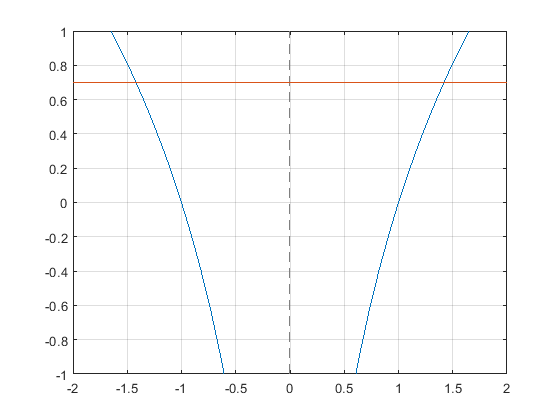

axis([-2 2 -1 1]);
grid on;

%a) graficamente las raices son aproximadamente 1.4
xl = 0.5;
xu = 2;
f=@(x) log(x^2)-0.7;
[xr1,i1]=BiseccionMetodo(f,xl,xu)

xr1 = 1.4191

i1 = 53

[xr2,i2]=interLin(f,xl,xu)

xr2 = 1.4191

i2 = 55

[xr3,i3]=nr(f, xu)

xr3 = 1.4191

i3 = 5

Escribe aquí las funciones bisección, interpolación lineal y Newton-Raphson.

function [xr,i]=nr(f, xu)
%Hallar la raíz de la funcion f entre xl y xu. Empleando el método de
%Newton Rapsohd

     MAX = 52;
     tolerancia = eps;
     i = 0;
     condicion= true;
     fx=sym(f);
     dfs= diff(fx);
     df=matlabFunction(dfs);
     xr= xu-(f(xu)/df(xu));
     
     while condicion
         xu=xr;
         xr= xu-(f(xu)/df(xu));
         i=i+1;
         condicion= abs((xr-xu)/xr) > tolerancia  && i < MAX;
         
     end
     
end
function [xr,i]=interLin(f,xl,xu)
%Hallar la raíz de la funcion f entre xl y xu. Empleando el método de
%interpolación lineal

% f(xl) y f(xu) tienen que tener signos diferentes, sino la función no va a
    % poder trabajar.
     if sign(f(xl))*sign(f(xu)) >= 0
        error('f(xl)f(xu) < 0 no se satisface')
     end

     MAX = 55;
     tolerancia = eps;
     xr=xu-((f(xu)*(xl-xu))/(f(xl)-f(xu)));
     condicion=true;
     fx = f(xr);
     i = 0;

     while condicion
         if sign(fx) ~= sign(f(xl))
             xu = xr;
         else
             xl = xr;
         end
         xr=xu-((f(xu)*(xl-xu))/(f(xl)-f(xu)));
         fx=f(xr);
         i=i+1;
         condicion= abs((xu-xl)/xu) > tolerancia && fx~=0 && i < MAX;
     end
end

function [xr,i]=BiseccionMetodo(f,xl,xu)
%Hallar la raíz de la funcion f entre xl y xu. Empleando el método de
%bisección

% f(xl) y f(xu) tienen que tener signos diferentes, sino la función no va a
    % poder trabajar.
     if sign(f(xl))*sign(f(xu)) >= 0
        error('f(xl)f(xu) < 0 no se satisface')
     end

     MAX = 55;
     tolerancia = eps;
     xr = (xl+xu)/2;
     fx = f(xr);
     i = 0;

     while abs((xu-xl)/xu) > tolerancia && fx~=0 && i < MAX
         if sign(fx) ~= sign(f(xl))
             xu = xr;
         else
             xl = xr;
         end
         xr=(xl+xu)/2;
         fx=f(xr);
         i=i+1;
     end
end